%% ===============================================================
%  Plane stress FEM parametric + TWO neural networks predicting full "u" for body forces in x and y direction separately
%  - All comments and printed messages are in English
%  - Input normalized to [-1,1], outputs normalized with z-score (per DOF)
%  - Minibatch training using dlnetwork + Adam
%  - Full inference and comparison with FEM
%  Mesh: 6 x 6 nodes (same as requested)
%  Elastic modulus E = 1, nu = 0.3
% ===============================================================

clear; close all; clc;

%% ===============================================================
% 1️⃣  PROBLEM PARAMETERS AND DOMAIN
% ===============================================================
nNodesX = 8;
nNodesY = 8;
nNodes = nNodesX * nNodesY;

dim_list = [3 6 12 24];

L2_error = [];
RMSE_error = [];
Linf_error = [];

Max_B_H = []; %max base and height values
k = 1;

for d = 1:length(dim_list)

    dim = dim_list(d);

    fprintf(' 🟡 Program no. %d:\nB and H range from 1 to %d',k,dim);

    B_min = 1;  B_max = dim;     % base range
    H_min = 1;  H_max = dim;     % height range
    nSamples = 1000;           % number of geometries for training
    
    % Material (constant)
    E = 1;
    nu = 0.3;
    
    % Reference unit mesh
    [xGrid, yGrid] = meshgrid(linspace(0,1,nNodesX), linspace(0,1,nNodesY));
    coords0 = [xGrid(:), yGrid(:)];
    
    % DOF per node and totals
    ndofNode = 2;
    nDOF = nNodes * ndofNode;
    
    % fprintf('Problem: %d nodes (%dx%d) -> %d DOFs\n', nNodes, nNodesX, nNodesY, nDOF);
    
    %% ===============================================================
    % 2️⃣  DATASET CREATION (FEM) - body force applied to entire plate
    %     Base (bottom, y==0) is fixed a priori in dataset and training
    % ===============================================================
    % Body force per unit volume (fx, fy)
    bodyForcex = [1; 0];
    bodyForcey = [0; 1];
    
    % Preallocate geometry matrix and outputs (outputs = full displacement vector u)
    Xdata = zeros(2, nSamples);   % [B; H]
    Uall  = zeros(nDOF, nSamples);% each column is full displacement vector for that sample
    
    % fprintf('Generating FEM dataset (%d samples) with base fixed (y==0)...\n', nSamples);
    
    for i = 1:nSamples
        % random geometric parameters
        B = B_min + (B_max - B_min) * rand();
        H = H_min + (H_max - H_min) * rand();
        Xdata(:,i) = [B; H];
    
        % physical coordinates scaled
        coords = [coords0(:,1)*B, coords0(:,2)*H];
    
        % build FEM stiffness and force
        [K1, F1] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyForcex);
        [K2, F2] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyForcey);
        
        % identify base nodes (y == 0) -> fixed
        tol = 1e-12;
        baseNodes = find(abs(coords(:,2) - 0) < tol); % bottom side, coords(i,2) → y-coordinate of node i
        fixedDOFs = reshape([ (baseNodes-1)'*ndofNode + 1 ; (baseNodes-1)'*ndofNode + 2 ], [], 1);
    
        % free DOFs
        allDOFs = (1:nDOF)';
        freeDOFs = setdiff(allDOFs, fixedDOFs);
    
        % Solve for displacements: u(free) = K_ff \ F_f
        u1 = zeros(nDOF,1);
        u1(freeDOFs) = K1(freeDOFs, freeDOFs) \ F1(freeDOFs);
    
        u2 = zeros(nDOF,1);
        u2(freeDOFs) = K2(freeDOFs, freeDOFs) \ F2(freeDOFs);
    
        % Uall(:,i) = u;
        Uall1(:,i) = u1;
        Uall2(:,i) = u2;
   
    end
    
    % Ux_energy = norm(Uall2(1:2:end,:),'fro');
    % Uy_energy = norm(Uall2(2:2:end,:),'fro');
    % fprintf('Energy ratio Uy/Ux = %.3e\n', Uy_energy/Ux_energy);
    
    % disp('✅ FEM dataset generated.');
    
    %% ===============================================================
    % 3️⃣  DATA PREPARATION AND NORMALIZATION
    %     - Input normalization to [-1,1]
    %     - Output normalization: z-score per DOF
    % ===============================================================
    % Input normalization to [-1,1]
    Bnorm = 2*(Xdata(1,:) - B_min)/(B_max - B_min) - 1; 
    Hnorm = 2*(Xdata(2,:) - H_min)/(H_max - H_min) - 1;
    Xnorm = [Bnorm; Hnorm];
    
    % Output normalization (z-score) per DOF (row-wise)
    epsVal = 1e-8;
    
    mu_U1 = mean(Uall1,2);
    sigma_U1 = std(Uall1,0,2) + epsVal; 
    Uall_norm1 = (Uall1 - mu_U1) ./ sigma_U1;
    
    mu_U2 = mean(Uall2,2); 
    sigma_U2 = std(Uall2,0,2) + epsVal;
    Uall_norm2 = (Uall2 - mu_U2) ./ sigma_U2;
    
    % Convert to single for speed (optional)
    Xn = single(Xnorm);
    Un1 = single(Uall_norm1);
    Un2 = single(Uall_norm2);
    
    % Create dlarray for input when needed; minibatches will be formed manually
    dlXall = dlarray(Xn, "CB"); 
    
    %% ===============================================================
    % 4️⃣  DEFINE SINGLE NETWORK (mapping 2 -> nDOF)
    % ===============================================================
    % Simple fully-connected network for body force x (NN1)
    nOut = nDOF;
    layers1 = [
        featureInputLayer(2,"Normalization","none") %2 input features;
        fullyConnectedLayer(64)
        tanhLayer
        fullyConnectedLayer(64)
        tanhLayer
        fullyConnectedLayer(nOut)
    ];
    dlnet1 = dlnetwork(layerGraph(layers1));
    
    % Simple fully-connected network for body force y (NN2)
    layers2 = [
        featureInputLayer(2,"Normalization","none") %2 input features;
        fullyConnectedLayer(64)
        tanhLayer
        fullyConnectedLayer(64)
        tanhLayer
        fullyConnectedLayer(nOut)
    ];
    dlnet2 = dlnetwork(layerGraph(layers2));
    
    %% ===============================================================
    % 5️⃣  TRAINING (minibatch) - manual loop with Adam
    %% ===============================================================
    numEpochs = 1000;
    learnRate = 1e-3; 
    miniBatchSize = 200;
    
    avgGrad1 = [];
    avgSqGrad1 = []; 
    avgGrad2 = [];
    avgSqGrad2 = [];
    
    numIterationsPerEpoch = ceil(nSamples / miniBatchSize);
    
    disp('🚀 Starting training single network (minibatch Adam)...');
    
    for epoch = 1:numEpochs
        idx = randperm(nSamples);
    
        for it = 1:numIterationsPerEpoch
            batchStart = (it-1)*miniBatchSize + 1;
            batchEnd = min(it*miniBatchSize, nSamples);
            batchIdx = idx(batchStart:batchEnd);
    
            % form minibatch
            Xbatch = dlarray(Xn(:,batchIdx), "CB");
            Ybatch1 = dlarray(Un1(:,batchIdx), "CB");
            Ybatch2 = dlarray(Un2(:,batchIdx), "CB");
    
            % compute loss and gradients for NN1 & NN2
            [loss1, gradients1] = dlfeval(@modelLoss, dlnet1, Xbatch, Ybatch1);
            [loss2, gradients2] = dlfeval(@modelLoss, dlnet2, Xbatch, Ybatch2);
    
            % update network parameters for NN1 & NN2 with Adam
            iteration = (epoch-1)*numIterationsPerEpoch + it;
            [dlnet1, avgGrad1, avgSqGrad1] = adamupdate(dlnet1, gradients1, avgGrad1, avgSqGrad1, iteration, learnRate);
            [dlnet2, avgGrad2, avgSqGrad2] = adamupdate(dlnet2, gradients2, avgGrad2, avgSqGrad2, iteration, learnRate);
    
    
        end
    
        if mod(epoch,100)==0 || epoch==1
            fprintf('Epoch %d/%d - Loss (NN1) %.3e ; Loss (NN2) %.3e\n', epoch, numEpochs, gather(extractdata(loss1)),  gather(extractdata(loss2)));
        end
    
        % optional LR schedule
        if epoch == round(0.7*numEpochs)
            learnRate = learnRate * 0.2;
            fprintf('Learning rate decreased to %.2e at epoch %d\n', learnRate, epoch);
        end
    end
    
    disp('✅ Training completed.');
    
    % Save trained network and normalization data for NN1
    save(['single_net_fullu_', num2str(nNodesX),'x',num2str(nNodesY), '.mat'], ...
        'dlnet1','B_min','B_max','H_min','H_max','mu_U1','sigma_U1', ...
        'nNodesX','nNodesY','E','nu','ndofNode');
    
    % Save trained network and normalization data for NN2
    save(['single_net_fullu_', num2str(nNodesX),'x',num2str(nNodesY), '.mat'], ...
        'dlnet2','B_min','B_max','H_min','H_max','mu_U2','sigma_U2', ...
        'nNodesX','nNodesY','E','nu','ndofNode');

 🟡 Program no. 1:
B and H range from 1 to 3

🚀 Starting training single network (minibatch Adam)...


Epoch 1/1000 - Loss (NN1) 9.307e-01 ; Loss (NN2) 8.111e-01
Epoch 100/1000 - Loss (NN1) 3.284e-03 ; Loss (NN2) 4.521e-03
Epoch 200/1000 - Loss (NN1) 8.184e-04 ; Loss (NN2) 1.215e-03
Epoch 300/1000 - Loss (NN1) 8.172e-04 ; Loss (NN2) 6.906e-04
Epoch 400/1000 - Loss (NN1) 4.847e-04 ; Loss (NN2) 3.017e-04
Epoch 500/1000 - Loss (NN1) 1.386e-04 ; Loss (NN2) 2.175e-04
Epoch 600/1000 - Loss (NN1) 9.969e-05 ; Loss (NN2) 1.312e-04
Epoch 700/1000 - Loss (NN1) 5.938e-05 ; Loss (NN2) 8.289e-05


Learning rate decreased to 2.00e-04 at epoch 700


Epoch 800/1000 - Loss (NN1) 5.770e-05 ; Loss (NN2) 8.028e-05
Epoch 900/1000 - Loss (NN1) 4.741e-05 ; Loss (NN2) 7.525e-05
Epoch 1000/1000 - Loss (NN1) 4.058e-05 ; Loss (NN2) 5.313e-05


✅ Training completed.


 🟡 Program no. 2:
B and H range from 1 to 6

🚀 Starting training single network (minibatch Adam)...


Epoch 1/1000 - Loss (NN1) 8.271e-01 ; Loss (NN2) 8.058e-01
Epoch 100/1000 - Loss (NN1) 6.007e-03 ; Loss (NN2) 1.634e-02
Epoch 200/1000 - Loss (NN1) 6.896e-03 ; Loss (NN2) 2.241e-03
Epoch 300/1000 - Loss (NN1) 8.377e-04 ; Loss (NN2) 9.251e-04
Epoch 400/1000 - Loss (NN1) 1.469e-03 ; Loss (NN2) 3.972e-04
Epoch 500/1000 - Loss (NN1) 3.504e-04 ; Loss (NN2) 1.754e-04
Epoch 600/1000 - Loss (NN1) 3.960e-04 ; Loss (NN2) 1.109e-04
Epoch 700/1000 - Loss (NN1) 4.741e-04 ; Loss (NN2) 8.977e-05


Learning rate decreased to 2.00e-04 at epoch 700


Epoch 800/1000 - Loss (NN1) 3.654e-04 ; Loss (NN2) 7.940e-05
Epoch 900/1000 - Loss (NN1) 2.101e-04 ; Loss (NN2) 6.233e-05
Epoch 1000/1000 - Loss (NN1) 2.016e-04 ; Loss (NN2) 5.913e-05


✅ Training completed.


 🟡 Program no. 3:
B and H range from 1 to 12

🚀 Starting training single network (minibatch Adam)...


Epoch 1/1000 - Loss (NN1) 2.290e-01 ; Loss (NN2) 8.393e-01
Epoch 100/1000 - Loss (NN1) 2.135e-02 ; Loss (NN2) 1.570e-02
Epoch 200/1000 - Loss (NN1) 7.530e-02 ; Loss (NN2) 2.650e-03
Epoch 300/1000 - Loss (NN1) 3.354e-03 ; Loss (NN2) 9.529e-04
Epoch 400/1000 - Loss (NN1) 1.337e-03 ; Loss (NN2) 4.474e-04
Epoch 500/1000 - Loss (NN1) 5.600e-04 ; Loss (NN2) 2.551e-04
Epoch 600/1000 - Loss (NN1) 4.644e-04 ; Loss (NN2) 2.547e-04
Epoch 700/1000 - Loss (NN1) 6.532e-04 ; Loss (NN2) 1.947e-04


Learning rate decreased to 2.00e-04 at epoch 700


Epoch 800/1000 - Loss (NN1) 2.212e-03 ; Loss (NN2) 1.865e-04
Epoch 900/1000 - Loss (NN1) 3.340e-04 ; Loss (NN2) 1.782e-04
Epoch 1000/1000 - Loss (NN1) 5.376e-04 ; Loss (NN2) 1.264e-04


✅ Training completed.


 🟡 Program no. 4:
B and H range from 1 to 24

🚀 Starting training single network (minibatch Adam)...


Epoch 1/1000 - Loss (NN1) 1.020e+00 ; Loss (NN2) 9.181e-01
Epoch 100/1000 - Loss (NN1) 4.428e-01 ; Loss (NN2) 1.433e-02
Epoch 200/1000 - Loss (NN1) 8.112e-02 ; Loss (NN2) 2.586e-03
Epoch 300/1000 - Loss (NN1) 8.373e-02 ; Loss (NN2) 9.465e-04
Epoch 400/1000 - Loss (NN1) 3.900e-02 ; Loss (NN2) 5.364e-04
Epoch 500/1000 - Loss (NN1) 5.381e-03 ; Loss (NN2) 5.357e-04
Epoch 600/1000 - Loss (NN1) 4.867e-04 ; Loss (NN2) 2.773e-04
Epoch 700/1000 - Loss (NN1) 1.884e-03 ; Loss (NN2) 2.521e-04


Learning rate decreased to 2.00e-04 at epoch 700


Epoch 800/1000 - Loss (NN1) 3.779e-04 ; Loss (NN2) 2.421e-04
Epoch 900/1000 - Loss (NN1) 3.525e-03 ; Loss (NN2) 2.069e-04
Epoch 1000/1000 - Loss (NN1) 4.162e-03 ; Loss (NN2) 1.865e-04


✅ Training completed.


    
    %% ===============================================================
    %  INFERENCE + COMPARISON WITH FEM
    %  (we predict full u from the single network, then de-normalize)
    % ===============================================================
    Btest = 0.7 * B_max;
    Htest = 0.6 * H_max;
    
    % --- Normalize geometry input ---
    Bnorm_t = 2*(Btest - B_min)/(B_max - B_min) - 1;
    Hnorm_t = 2*(Htest - H_min)/(H_max - H_min) - 1;
    dlGeom = dlarray(single([Bnorm_t; Hnorm_t]), "CB");
    
    % --- Predict normalized u for body force x & y (NN1 & NN2) ---
    u_norm_dl1 = predict(dlnet1, dlGeom);
    u_norm1 = double(extractdata(u_norm_dl1));
    u_norm_dl2 = predict(dlnet2, dlGeom);
    u_norm2 = double(extractdata(u_norm_dl2));
    
    % --- De-normalize to physical scale ---
    u_pred1 = (u_norm1 .* mu_U1*0 + 0); 
    u_pred1 = (u_norm1 .* sigma_U1) + mu_U1;
    
    u_pred2 = (u_norm2 .* mu_U2*0 + 0); 
    u_pred2 = (u_norm2 .* sigma_U2) + mu_U2;
    
    % --- FEM solution for the same geometry (base fixed) ---
    coords = [coords0(:,1)*Btest, coords0(:,2)*Htest];
    [K1, F1] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyForcex);
    [K2, F2] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyForcey);
    
    % apply base fixed BC (y==0)
    tol = 1e-12;
    baseNodes = find(abs(coords(:,2) - 0) < tol);
    fixedDOFs = reshape([ (baseNodes-1)'*ndofNode + 1 ; (baseNodes-1)'*ndofNode + 2 ], [], 1);
    allDOFs = (1:nDOF)';
    freeDOFs = setdiff(allDOFs, fixedDOFs);
    
    u_fem1 = zeros(nDOF,1);
    u_fem2 = zeros(nDOF,1);
    
    u_fem1(freeDOFs) = K1(freeDOFs, freeDOFs) \ F1(freeDOFs);
    u_fem2(freeDOFs) = K2(freeDOFs, freeDOFs) \ F2(freeDOFs);
    
    % --- Compare FEM vs NN ---
    u_NN1= u_pred1(:);
    u_FEM1 = u_fem1(:);
    u_NN2 = u_pred2(:);
    u_FEM2 = u_fem2(:);
    
    % extract u_x and u_y components
    u_x_FEM1 = u_FEM1(1:2:end);
    u_y_FEM1 = u_FEM1(2:2:end);
    u_x_NN1  = u_NN1(1:2:end);
    u_y_NN1  = u_NN1(2:2:end);
    
    u_x_FEM2 = u_FEM2(1:2:end);
    u_y_FEM2 = u_FEM2(2:2:end);
    u_x_NN2  = u_NN2(1:2:end);
    u_y_NN2  = u_NN2(2:2:end);
    
    % reshape on grid
    Xcoords = reshape(coords(:,1), nNodesY, nNodesX);
    Ycoords = reshape(coords(:,2), nNodesY, nNodesX);
    
    UxF1 = reshape(u_x_FEM1, nNodesY, nNodesX);
    UyF1 = reshape(u_y_FEM1, nNodesY, nNodesX);
    UxN1 = reshape(u_x_NN1,  nNodesY, nNodesX);
    UyN1 = reshape(u_y_NN1,  nNodesY, nNodesX);
    
    UxF2 = reshape(u_x_FEM2, nNodesY, nNodesX);
    UyF2 = reshape(u_y_FEM2, nNodesY, nNodesX);
    UxN2 = reshape(u_x_NN2,  nNodesY, nNodesX);
    UyN2 = reshape(u_y_NN2,  nNodesY, nNodesX);
    
    UxF = UxF1 + UxF2;
    UyF = UyF1 + UyF2;
    UxN = UxN1 + UxN2;
    UyN = UyN1 + UyN2;
    
    %error
    Err_u = abs(UxF - UxN);
    Err_v = abs(UyF - UyN);
    % Err_u1 = abs(UxF1 - UxN1);
    % Err_v1 = abs(UyF1 - UyN1);
    % Err_u2 = abs(UxF2 - UxN2);
    % Err_v2 = abs(UyF2 - UyN2);

    u_FEM = u_FEM1 + u_FEM2;
    u_NN  = u_NN1  + u_NN2;
    
    % ERROR METRICS (FULL DOF VECTOR)
    err_vec = u_FEM - u_NN;
    e = err_vec;
    u_ref = u_FEM;

    RMSE   = norm(e) / sqrt(numel(e));
    relL2  = norm(e) / norm(u_ref);
    maxErr = norm(e, Inf) / norm(u_ref, Inf);

    fprintf('RMSE   : %.3e\n', RMSE);
    fprintf('rel L2 : %.3e\n', relL2);
    fprintf('rel Linf: %.3e\n', maxErr);
    
    L2_error(k) = relL2;
    RMSE_error(k) = RMSE;
    Linf_error(k) = maxErr;

    Max_B_H(k)   = dim;
    k = k + 1;
    
end

RMSE   : 3.374e-02


rel L2 : 8.562e-03


rel Linf: 1.817e-02


RMSE   : 2.007e-01


rel L2 : 1.273e-02


rel Linf: 3.128e-02


RMSE   : 2.337e+00


rel L2 : 3.707e-02


rel Linf: 7.185e-02


RMSE   : 9.578e+01


rel L2 : 3.798e-01


rel Linf: 6.818e-01


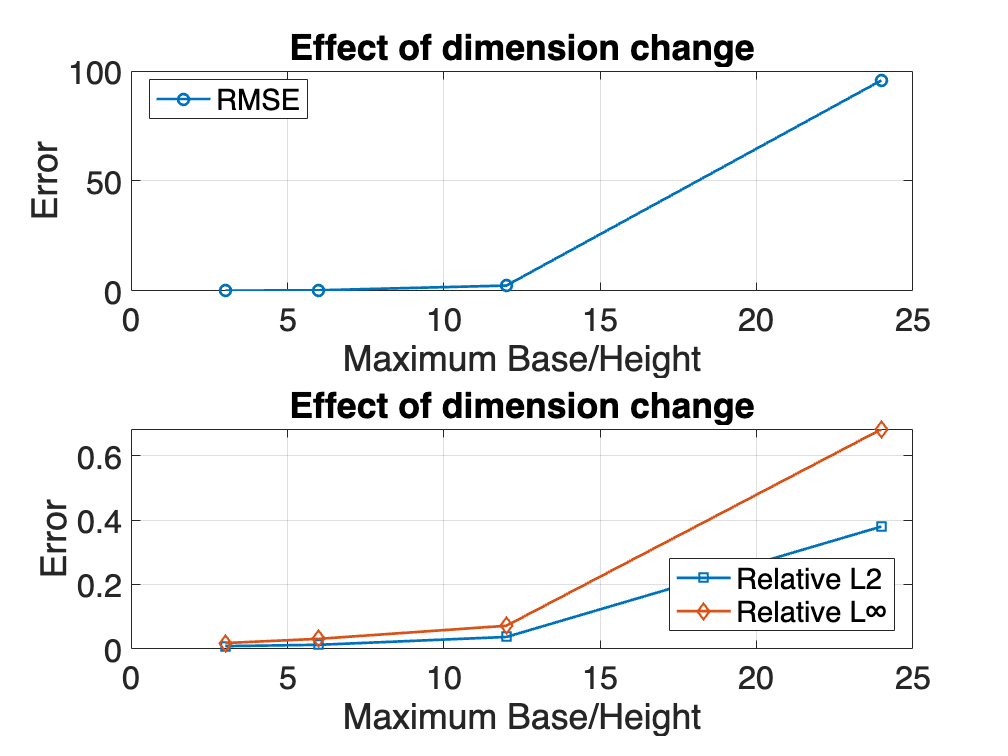

% disp(error_NN1);
% disp(Max_B_H);
set(groot, ...
    'DefaultAxesFontSize', 20, ...     % For ticks, x/y/z labels
    'DefaultTextFontSize', 20, ...     % For manually added text objects
    'DefaultLegendFontSize', 20);      % For graph legends

figure;
subplot(2,1,1)
plot(Max_B_H, RMSE_error, '-o', 'LineWidth',1.5);

legend ('RMSE', 'Location',['best']);
xlabel('Maximum Base/Height');
ylabel('Error');
title ('Effect of dimension change');
grid on

subplot(2,1,2)
plot(Max_B_H, L2_error, '-s', 'LineWidth',1.5); hold on
plot(Max_B_H, Linf_error, '-d', 'LineWidth',1.5);

legend ('Relative L2', 'Relative L∞', 'Location',['best']);
xlabel('Maximum Base/Height');
ylabel('Error');
title ('Effect of dimension change');
grid on


% subplot(2,1,2)
% plot(Max_B_H, RMSE_error, '-o');
% xlabel('Maximum Base/Height');
% ylabel('Absolute RMSE Error');
% grid on


Conclusion: Rel L2 is also increasing because error grows faster than displacement magnitude.

It would remain constant only if:

-  increase training samples proportionally

- Or increase network width/depth

- Or nondimensionalize the problem properly

===============================================================

Local functions

===============================================================


function [K,F] = buildPlaneStressFEM(coords,nx,ny,E,nu,bodyForce)
    % Structured mesh of 4-node bilinear quadrilateral elements
    nNodes = nx*ny;
    nElemX = nx-1; nElemY = ny-1;
    nElem = nElemX * nElemY;
    ndofNode = 2;
    nDOF = nNodes * ndofNode; %total dof of system

    % element connectivity matrix
    %(ix, iy) is one quadrilateral element
    conn = zeros(nElem,4);
    for ix = 1:nElemX
        for jy = 1:nElemY
            n1 = (ix-1)*ny + jy;
            n2 = ix*ny + jy;
            n3 = ix*ny + (jy+1);
            n4 = (ix-1)*ny + (jy+1);
            e = (ix-1)*nElemY + jy; %This converts the 2D element index (ix, jy) into a single element number
            conn(e,:) = [n1 n2 n3 n4]; %Element e connects nodes n1, n2, n3, n4
        end
    end

    K = zeros(nDOF);
    F = zeros(nDOF,1);

    % Plane stress constitutive matrix
    D = E / (1 - nu^2) * [1, nu, 0;
                          nu, 1, 0;
                          0, 0, (1-nu)/2];

    % 2x2 Gauss
    gp = [-1/sqrt(3), 1/sqrt(3)];
    wgp = [1,1];

    for e = 1:nElem
        nodes = conn(e,:);
        xe = coords(nodes,1);
        ye = coords(nodes,2);

        %element stiffness and force matrix
        Ke = zeros(8,8);
        Fe = zeros(8,1);

        % Reduced integration term B0 for shear (as in original)
        xi = 0; eta = 0;
        [N0, dNdxi0, dNdeta0] = shape4(xi,eta);
        J0 = [dNdxi0'; dNdeta0'] * [xe, ye];
        detJ0 = det(J0);
        invJ0 = inv(J0);
        dN0 = [dNdxi0, dNdeta0] * invJ0;

        B0 = zeros(3,8);
        for a = 1:4
            dNx = dN0(a,1);
            dNy = dN0(a,2);
            col = (a-1)*2;
            B0(1, col + 1) = dNx;
            B0(2, col + 2) = dNy;
            B0(3, col + 1) = dNy;
            B0(3, col + 2) = dNx;
        end

        for i = 1:2
            for j = 1:2
                xi = gp(i); eta = gp(j);
                [N, dNdxi, dNdeta] = shape4(xi,eta);
                J = [dNdxi'; dNdeta'] * [xe, ye];
                detJ = det(J);
                invJ = inv(J);
                dN = [dNdxi, dNdeta] * invJ;

                B = zeros(3,8);
                for a = 1:4
                    dNx = dN(a,1);
                    dNy = dN(a,2);
                    col = (a-1)*2;
                    B(1, col + 1) = dNx;
                    B(2, col + 2) = dNy;
                    B(3, col + 1) = dNy;
                    B(3, col + 2) = dNx;
                end

                % replace shear row with reduced B0 shear row
                B(3,:) = B0(3,:);

                Ke = Ke + (B' * D * B) * detJ * wgp(i) * wgp(j);

                Nmat = zeros(2,8);
                for a = 1:4
                    Nmat(1, (a-1)*2 + 1) = N(a);
                    Nmat(2, (a-1)*2 + 2) = N(a);
                end
                Fe = Fe + (Nmat' * bodyForce) * detJ * wgp(i) * wgp(j);
            end
        end

        % assemble
        gdofs = zeros(8,1);
        for a = 1:4
            node = nodes(a);
            gdofs((a-1)*2 + (1:2)) = (node-1)*2 + (1:2);
        end
        K(gdofs, gdofs) = K(gdofs, gdofs) + Ke;
        F(gdofs) = F(gdofs) + Fe;
    end
end

function [N, dNdxi, dNdeta] = shape4(xi,eta)
    N = 0.25*[(1-xi)*(1-eta);
              (1+xi)*(1-eta);
              (1+xi)*(1+eta);
              (1-xi)*(1+eta)];
    dNdxi  = 0.25*[-(1-eta); (1-eta); (1+eta); -(1+eta)];
    dNdeta = 0.25*[-(1-xi); -(1+xi); (1+xi);  (1-xi)];
end

function [loss,gradients] = modelLoss(dlnet,X,Y)
    % Simple MSE loss for single network
    Ypred = forward(dlnet,X);
    loss = mean((Ypred - Y).^2,'all');
    gradients = dlgradient(loss, dlnet.Learnables);
end

